stockdata=readtable('stock_data.csv');
prices=table2array(stockdata(:,3:end))

prices =   101.5500  210.8319  139.0170  575.4300   17.8041  243.3900  141.3053   11.3535   74.9216  148.8400
  102.8200  212.1601  139.6465  573.1400   17.6405  246.4600  141.7896   11.3092   71.8236  145.7200
  104.3800  219.1003  140.9385  590.6500   17.6732  250.6467  144.1819   11.7166   71.6073  145.2500
  106.1500  224.5026  141.8265  593.2600   17.7910  251.2133  145.1507   12.1417   73.4366  146.6800
  105.8000  220.4983  142.6330  592.3900   17.7517  258.1300  145.2397   12.2037   74.0168  147.3600
  108.1600  216.2942  141.5010  592.6400   17.9284  263.7867  143.7074   12.5402   73.8398  148.6500
  101.5200  206.6978  136.1840  583.8500   17.8237  259.1867  140.2870   12.6731   75.0691  149.1100
  100.3500  204.8803  134.5210  599.0600   17.9284  260.4367  141.1965   12.6642   76.1018  151.6000
  102.9000  206.8676  133.2655  610.3400   17.6732  258.4933  139.8817   12.5402   76.1116  154.0700
  102.4500  207.1272  136.4625  613.1500   17.7714  258.4067  141.0185   12.5402  

retdata=price2ret(prices)

retdata =     0.0124    0.0063    0.0045   -0.0040   -0.0092    0.0125    0.0034   -0.0039   -0.0422   -0.0212
    0.0151    0.0322    0.0092    0.0301    0.0019    0.0168    0.0167    0.0354   -0.0030   -0.0032
    0.0168    0.0244    0.0063    0.0044    0.0066    0.0023    0.0067    0.0356    0.0252    0.0098
   -0.0033   -0.0180    0.0057   -0.0015   -0.0022    0.0272    0.0006    0.0051    0.0079    0.0046
    0.0221   -0.0193   -0.0080    0.0004    0.0099    0.0217   -0.0106    0.0272   -0.0024    0.0087
   -0.0634   -0.0454   -0.0383   -0.0149   -0.0059   -0.0176   -0.0241    0.0105    0.0165    0.0031
   -0.0116   -0.0088   -0.0123    0.0257    0.0059    0.0048    0.0065   -0.0007    0.0137    0.0166
    0.0251    0.0097   -0.0094    0.0187   -0.0143   -0.0075   -0.0094   -0.0098    0.0001    0.0162
   -0.0044    0.0013    0.0237    0.0046    0.0055   -0.0003    0.0081         0    0.0146    0.0286
   -0.0208   -0.0499   -0.0200   -0.0161    0.0033    0.0081   -0.0249    0.0133 

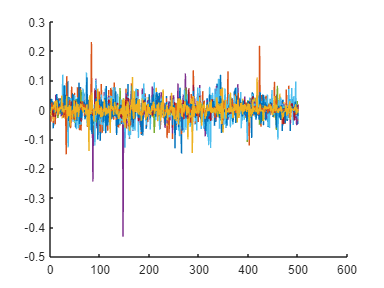

figure
hold on
for i = 1:10
    plot(retdata(:,i));
end
hold off

partition=cvpartition(501,"Holdout",.2);
traindata = retdata(training(partition),:);
testdata = retdata(test(partition),:);

[traincoeff,trainscore,trainlatent,traintsquared,trainexplained,trainmu] = pca(traindata);
[testcoeff,testscore,testlatent,testtsquared,testexplained,testmu] = pca(testdata);

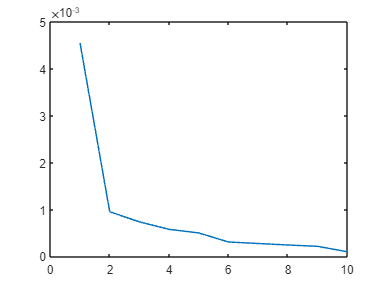

plot(trainlatent);

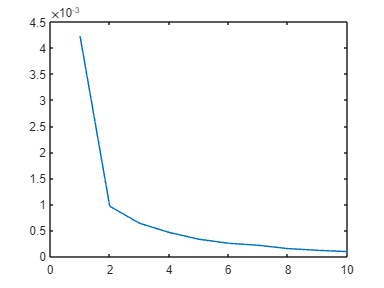

plot(testlatent);

pcs = trainexplained(1:4)

pcs =    53.6864
   11.2614
    8.7115
    6.8228
